we declare the parameters defining the geometry of the domain

D = 0.15;              %diameter of pipe in meters
Wb = 0.45;             %bulk velocity at inlet in m/s
rho = 910;             %density in kg/m^3
ni = 3.5 * 10^(-4);    %kynematic viscosity in m^2/s
mu = rho * ni;         %dynamic viscosity in Pa * s

%import the simulation data to be processed
data_simulation('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\length2,25-10x300.phi', 'C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\length2,25-10x300.mat')

NVariabili = 6

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\length2,25-10x300.mat')

Now we want to plot the variation along z of the z-velocity, to see where it starts to be negligible, that is where the flow can be considered fully developed. Note that DWDZ is stored in the centre of the cells in Phoenics, while W1 is stored in the 'H'  faces.

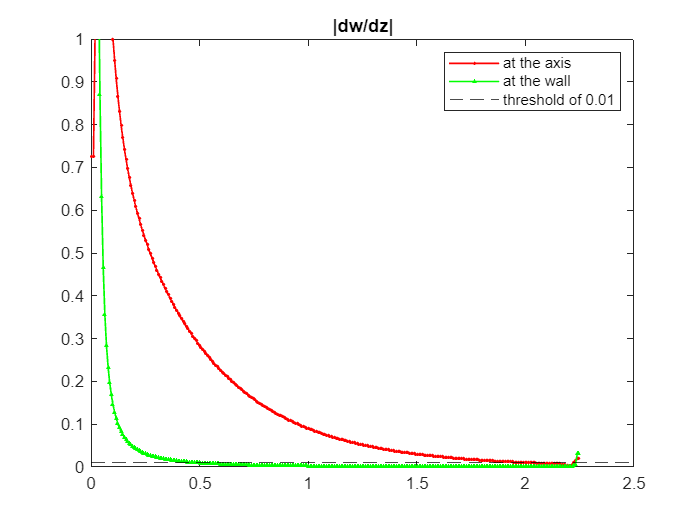

Z_C = squeeze(Z_C);
DWDZ = squeeze(DWDZ);

figure()
plot(Z_C, abs(DWDZ(1, :)), 'r-o', 'LineWidth', 1, 'MarkerSize', 1);
hold on;
plot(Z_C, abs(DWDZ(10, :)), 'g-^', 'LineWidth', 1, 'MarkerSize', 1);
yline(0.01, 'k--')
title('|dw/dz|')
legend('at the axis', 'at the wall', 'threshold of 0.01')
ylim([0, 1])
hold off;

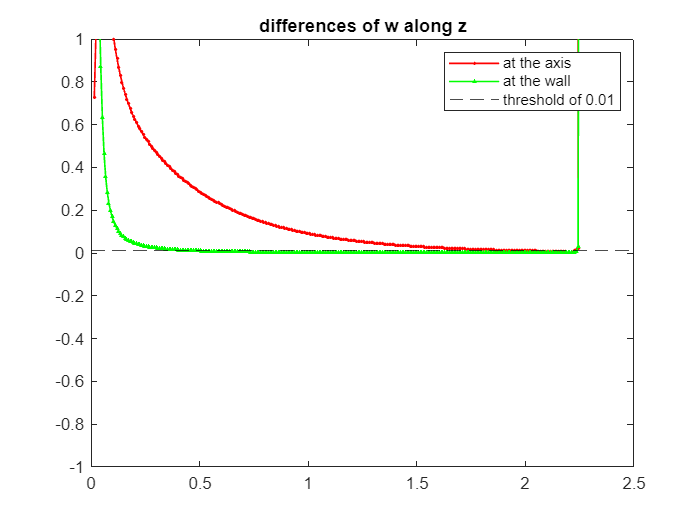

W1 = squeeze(W1);
Z_H = squeeze(Z_H);
diff = (W1(:, 2:end) - W1(:, 1:end-1))./(Z_H(2:end)-Z_H(1:end-1));
figure()
plot(Z_H(2:end), abs(diff(1, :)), 'r-o', 'LineWidth', 1, 'MarkerSize', 1);
hold on;
plot(Z_H(2:end), abs(diff(10, :)), 'g-^', 'LineWidth', 1, 'MarkerSize', 1);
yline(0.01, 'k--')
title('differences of w along z')
legend('at the axis', 'at the wall', 'threshold of 0.01')
ylim([-1, 1])
hold off;

%Now we obtain the first value such that the derivative is under the
%threshold
threshold = 0.01;
under_th = abs(DWDZ) < threshold

under_th = 10×300 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0

[~, idx_1] = max(under_th(1, :))

idx_1 = 270

[~, idx_10] = max(under_th(10, :))

idx_10 = 66

Now to check for the physical soundness of the solution, we plot the pression and velocity profiles along some segments

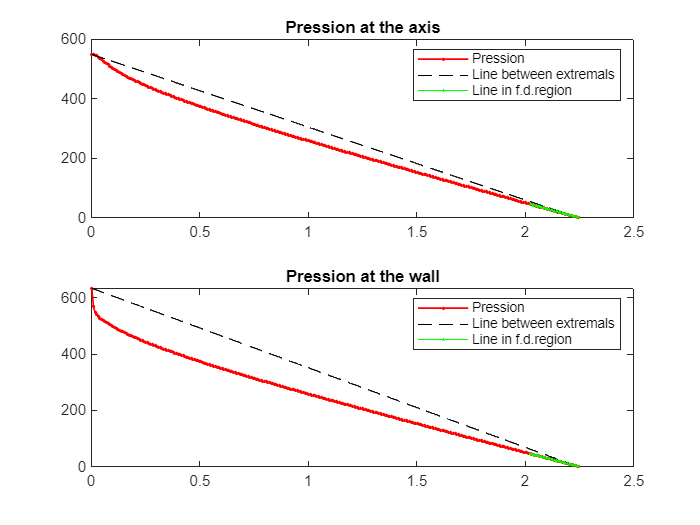

Z_C = squeeze(Z_C);
P1 = squeeze(P1);
figure()
subplot(2, 1, 1)
plot(Z_C, P1(1, :), 'r-o', 'LineWidth', 1, 'MarkerSize', 1)
hold on;
plot(Z_C, (P1(1, end)-P1(1, 1))/(Z_C(end)-Z_C(1)).*Z_C  + P1(1, 1), 'k--')
m = (P1(1, end)-P1(1, 270))/(Z_C(end)-Z_C(270));
intercept = P1(1, end) - m*Z_C(end);
plot(Z_C(270:end), m*Z_C(270:end) + intercept, 'g-^', 'MarkerSize', 1)
title("Pression at the axis")
legend("Pression", "Line between extremals", 'Line in f.d.region')
hold off

subplot(2, 1, 2)
plot(Z_C, P1(10, :), 'r-o', 'LineWidth', 1, 'MarkerSize', 1)
hold on;
plot(Z_C, (P1(10, end)-P1(10, 1))/(Z_C(end)-Z_C(1)).*Z_C  + P1(10, 1), 'k--')
m = (P1(10, end)-P1(10, 270))/(Z_C(end)-Z_C(270));
intercept = P1(10, end) - m*Z_C(end);
plot(Z_C(270:end), m*Z_C(270:end) + intercept, 'g-^', 'MarkerSize', 1)
title("Pression at the wall")
legend("Pression", "Line between extremals", 'Line in f.d.region')
hold off

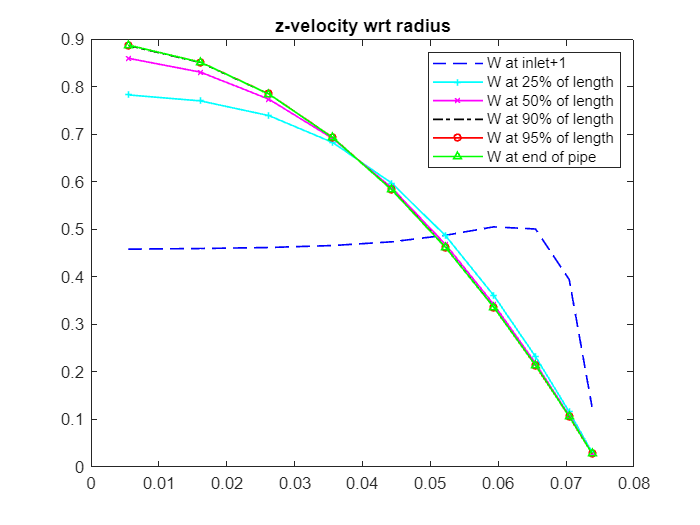

Y_C = squeeze(Y_C);
W1 = squeeze(W1);
figure()
plot(Y_C, W1(:, 2), 'b--', 'LineWidth', 1, 'MarkerSize', 4)
hold on;
plot(Y_C, W1(:, 75), 'c-+', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C, W1(:, 150), 'm-x', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C, W1(:, 270), 'k-.', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C, W1(:, 285), 'r-o', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C, W1(:, 299), 'g-^', 'LineWidth', 1, 'MarkerSize', 4)
title("z-velocity wrt radius")
legend("W at inlet+1", "W at 25% of length", "W at 50% of length", "W at 90% of length", "W at 95% of length", "W at end of pipe")
hold off

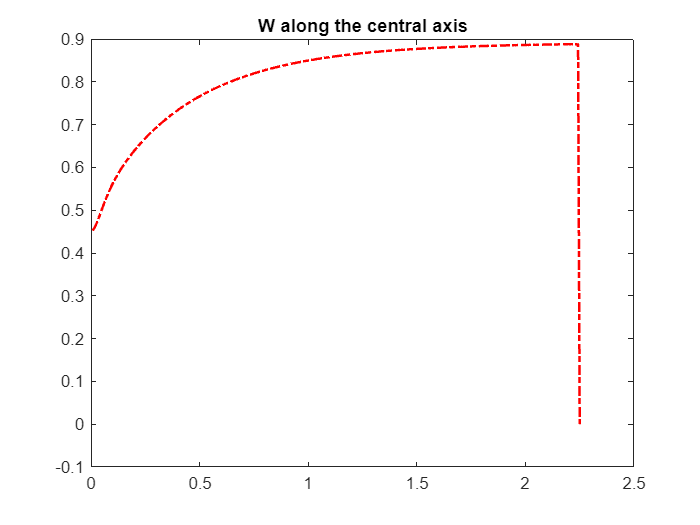

figure()
plot(Z_H, W1(1, :), 'r-.', 'LineWidth', 1.5)
title("W along the central axis")

The next graphs are intended to study the grid independence of the results

Import all of the simulation data:

%import the simulation data to be processed
data_simulation('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\reference.phi', 'C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\reference.mat')

NVariabili = 6

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\reference.mat')
P = squeeze(P1);
W = squeeze(W1);
dwdy = squeeze(DWDY);
YC = squeeze(Y_C);
YN = squeeze(Y_N);
ZC = squeeze (Z_C);
ZH = squeeze (Z_H);

data_simulation('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\z1.phi', 'C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\z1.mat')

NVariabili = 6

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\z1.mat')
Pz1 = squeeze(P1);
Wz1 = squeeze(W1);
dwdyz1 = squeeze(DWDY);
YCz1 = squeeze(Y_C);
YNz1 = squeeze(Y_N);
ZCz1 = squeeze (Z_C);
ZHz1 = squeeze (Z_H);

data_simulation('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\z2.phi', 'C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\z2.mat')

NVariabili = 6

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\z2.mat')
Pz2 = squeeze(P1);
Wz2 = squeeze(W1);
dwdyz2 = squeeze(DWDY);

YCz2 = squeeze(Y_C);
YNz2 = squeeze(Y_N);
ZCz2 = squeeze (Z_C);
ZHz2 = squeeze (Z_H);


data_simulation('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\y1.phi', 'C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\y1.mat')

NVariabili = 6

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\y1.mat')
Py1 = squeeze(P1);
Wy1 = squeeze(W1);
dwdyy1 = squeeze(DWDY);

YCy1 = squeeze(Y_C);
YNy1 = squeeze(Y_N);
ZCy1 = squeeze (Z_C);
ZHy1 = squeeze (Z_H);


data_simulation('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\y2.phi', 'C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\y2.mat')

NVariabili = 6

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\y2.mat')
Py2 = squeeze(P1);
Wy2 = squeeze(W1);
dwdyy2 = squeeze(DWDY);

YCy2 = squeeze(Y_C);
YNy2 = squeeze(Y_N);
ZCy2 = squeeze (Z_C);
ZHy2 = squeeze (Z_H);


data_simulation('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\yz1.phi', 'C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\yz1.mat')

NVariabili = 6

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\yz1.mat')
Pyz1 = squeeze(P1);
Wyz1 = squeeze(W1);
dwdyyz1 = squeeze(DWDY);

YCyz1 = squeeze(Y_C);
YNyz1 = squeeze(Y_N);
ZCyz1 = squeeze (Z_C);
ZHyz1 = squeeze (Z_H);


data_simulation('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\yz2.phi', 'C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\yz2.mat')

NVariabili = 6

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive\Desktop\Lab_tests\CFD1\2ndattempt\yz2.mat')
Pyz2 = squeeze(P1);
Wyz2 = squeeze(W1);
dwdyyz2 = squeeze(DWDY);

YCyz2 = squeeze(Y_C);
YNyz2 = squeeze(Y_N);
ZCyz2 = squeeze (Z_C);
ZHyz2 = squeeze (Z_H);


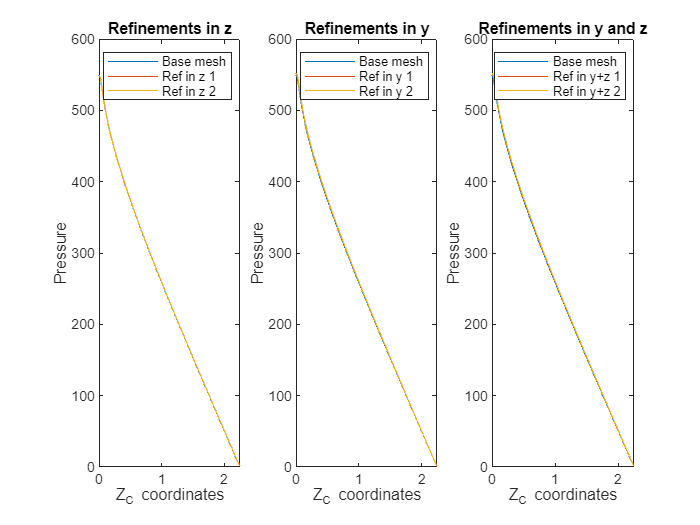

figure()
subplot(1, 3, 1)
plot(ZC, P(1, :), ZCz1, Pz1(1, :), ZCz2, Pz2(1, :))
legend('Base mesh', 'Ref in z 1', 'Ref in z 2')
xlabel('Z_C coordinates')
ylabel('Pressure')
title('Refinements in z')

subplot(1, 3, 2)
plot(ZC, P(1, :), ZCy1, Py1(1, :), ZCy2, Py2(1, :))
legend('Base mesh', 'Ref in y 1', 'Ref in y 2')
xlabel('Z_C coordinates')
ylabel('Pressure')
title('Refinements in y')

subplot(1, 3, 3)
plot(ZC, P(1, :), ZCyz1, Pyz1(1, :), ZCyz2, Pyz2(1, :))
legend('Base mesh', 'Ref in y+z 1', 'Ref in y+z 2')
xlabel('Z_C coordinates')
ylabel('Pressure')
title('Refinements in y and z')

refinements =   [length(ZC)*length(YC), length(ZCy1)*length(YCy1), length(ZCy2)*length(YCy2);
                 length(ZC)*length(YC), length(ZCz1)*length(YCz1), length(ZCz2)*length(YCz2);
                 length(ZC)*length(YC), length(ZCyz1)*length(YCyz1), length(ZCyz2)*length(YCyz2)];
delta_p =       [P(1, 1)-P(1, end), Py1(1, 1)-Py1(1, end), Py2(1, 1)-Py2(1, end);
                 P(1, 1)-P(1, end), Pz1(1, 1)-Pz1(1, end), Pz2(1, 1)-Pz2(1, end);
                 P(1, 1)-P(1, end), Pyz1(1, 1)-Pyz1(1, end), Pyz2(1, 1)-Pyz2(1, end)];

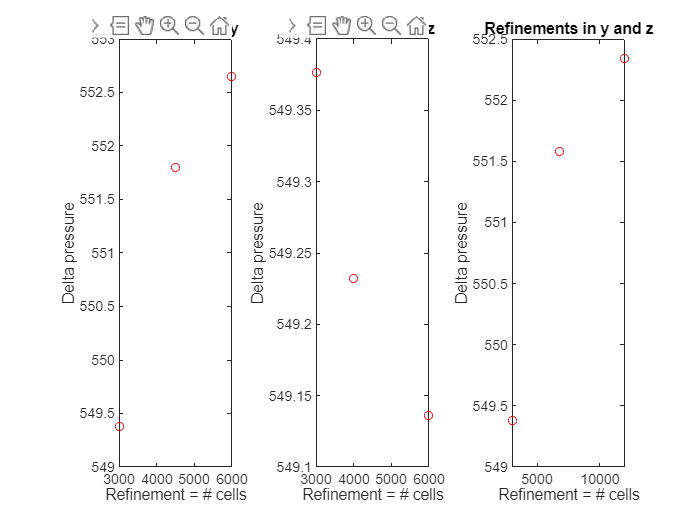

figure()
subplot(1, 3, 1)
plot(refinements(1, :), delta_p(1, :), 'ro', MarkerSize=5)
xlabel('Refinement = # cells')
ylabel('Delta pressure')
title('Refinements in y')

subplot(1, 3, 2)
plot(refinements(2, :), delta_p(2, :), 'ro', 'MarkerSize', 5)
xlabel('Refinement = # cells')
ylabel('Delta pressure')
title('Refinements in z')

subplot(1, 3, 3)
plot(refinements(3, :), delta_p(3, :), 'ro', 'MarkerSize', 5)
xlabel('Refinement = # cells')
ylabel('Delta pressure')
title('Refinements in y and z')

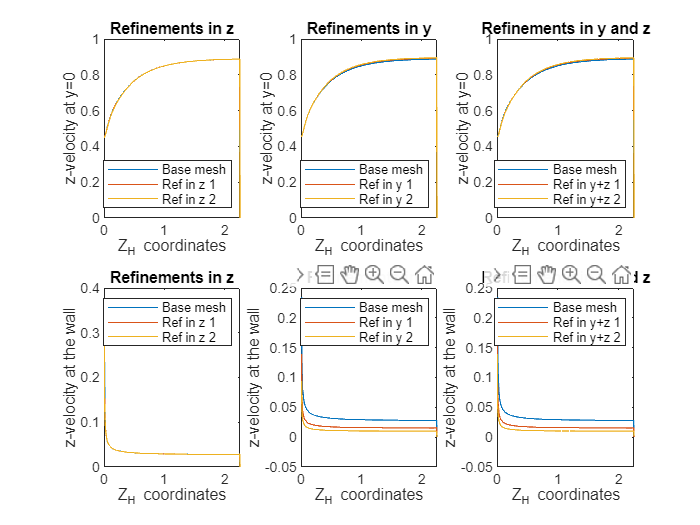

figure()
%At the central axis
subplot(2, 3, 1)
plot(ZH, W(1,:), ZHz1, Wz1(1,:), ZHz2, Wz2(1,:))
legend('Base mesh', 'Ref in z 1', 'Ref in z 2', 'Location','south')
xlabel('Z_H coordinates')
ylabel('z-velocity at y=0')
title('Refinements in z')

subplot(2, 3, 2)
plot(ZH, W(1,:), ZHy1, Wy1(1,:), ZHy2, Wy2(1,:))
legend('Base mesh', 'Ref in y 1', 'Ref in y 2', 'Location','south')
xlabel('Z_H coordinates')
ylabel('z-velocity at y=0')
title('Refinements in y')

subplot(2, 3, 3)
plot(ZH, W(1,:), ZHyz1, Wyz1(1,:), ZHyz2, Wyz2(1,:))
legend('Base mesh', 'Ref in y+z 1', 'Ref in y+z 2', 'Location','south')
xlabel('Z_H coordinates')
ylabel('z-velocity at y=0')
title('Refinements in y and z')

%Neat the wall
subplot(2, 3, 4)
plot(ZH, W(end,:), ZHz1, Wz1(end,:), ZHz2, Wz2(end,:))
legend('Base mesh', 'Ref in z 1', 'Ref in z 2', 'Location','north')
xlabel('Z_H coordinates')
ylabel('z-velocity at the wall')
title('Refinements in z')

subplot(2, 3, 5)
plot(ZH, W(end,:), ZHy1, Wy1(end,:), ZHy2, Wy2(end,:))
legend('Base mesh', 'Ref in y 1', 'Ref in y 2', 'Location','north')
xlabel('Z_H coordinates')
ylabel('z-velocity at the wall')
title('Refinements in y')

subplot(2, 3, 6)
plot(ZH, W(end,:), ZHyz1, Wyz1(end,:), ZHyz2, Wyz2(end,:))
legend('Base mesh', 'Ref in y+z 1', 'Ref in y+z 2', 'Location','north')
xlabel('Z_H coordinates')
ylabel('z-velocity at the wall')
title('Refinements in y and z')

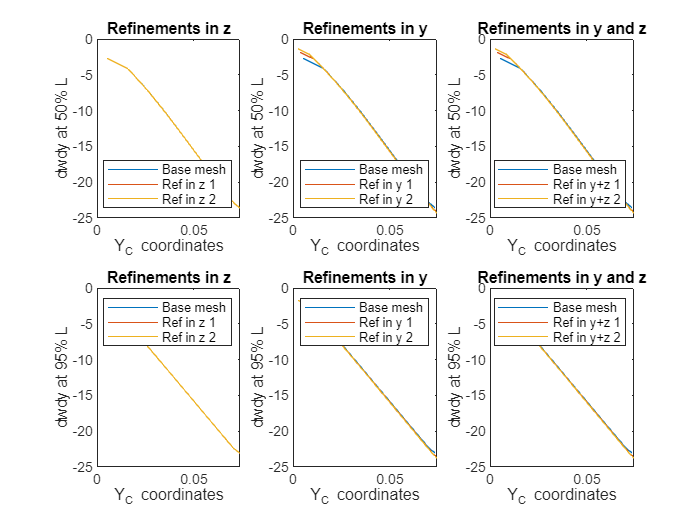

figure()
%At the 50% of length
subplot(2, 3, 1)
plot(YC, dwdy(:, ceil(end*0.5)), YCz1, dwdyz1(:, ceil(end*0.5)), YCz2, dwdyz2(:, ceil(end*0.5)))
legend('Base mesh', 'Ref in z 1', 'Ref in z 2', 'Location','south')
xlabel('Y_C coordinates')
ylabel('dwdy at 50% L')
title('Refinements in z')

subplot(2, 3, 2)
plot(YC, dwdy(:, ceil(end*0.5)), YCy1, dwdyy1(:, ceil(end*0.5)), YCy2, dwdyy2(:, ceil(end*0.5)))
legend('Base mesh', 'Ref in y 1', 'Ref in y 2', 'Location','south')
xlabel('Y_C coordinates')
ylabel('dwdy at 50% L')
title('Refinements in y')

subplot(2, 3, 3)
plot(YC, dwdy(:, ceil(end*0.5)), YCyz1, dwdyyz1(:, ceil(end*0.5)), YCyz2, dwdyyz2(:, ceil(end*0.5)))
legend('Base mesh', 'Ref in y+z 1', 'Ref in y+z 2', 'Location','south')
xlabel('Y_C coordinates')
ylabel('dwdy at 50% L')
title('Refinements in y and z')

%At 95% of length
subplot(2, 3, 4)
plot(YC, dwdy(:, ceil(end*0.95)), YCz1, dwdyz1(:, ceil(end*0.95)), YCz2, dwdyz2(:, ceil(end*0.95)))
legend('Base mesh', 'Ref in z 1', 'Ref in z 2', 'Location','north')
xlabel('Y_C coordinates')
ylabel('dwdy at 95% L')
title('Refinements in z')

subplot(2, 3, 5)
plot(YC, dwdy(:, ceil(end*0.95)), YCy1, dwdyy1(:, ceil(end*0.95)), YCy2, dwdyy2(:, ceil(end*0.95)))
legend('Base mesh', 'Ref in y 1', 'Ref in y 2', 'Location','north')
xlabel('Y_C coordinates')
ylabel('dwdy at 95% L')
title('Refinements in y')

subplot(2, 3, 6)
plot(YC, dwdy(:, ceil(end*0.95)), YCyz1, dwdyyz1(:, ceil(end*0.95)), YCyz2, dwdyyz2(:, ceil(end*0.95)))
legend('Base mesh', 'Ref in y+z 1', 'Ref in y+z 2', 'Location','north')
xlabel('Y_C coordinates')
ylabel('dwdy at 95% L')
title('Refinements in y and z')

Validation (benchmarking) plots

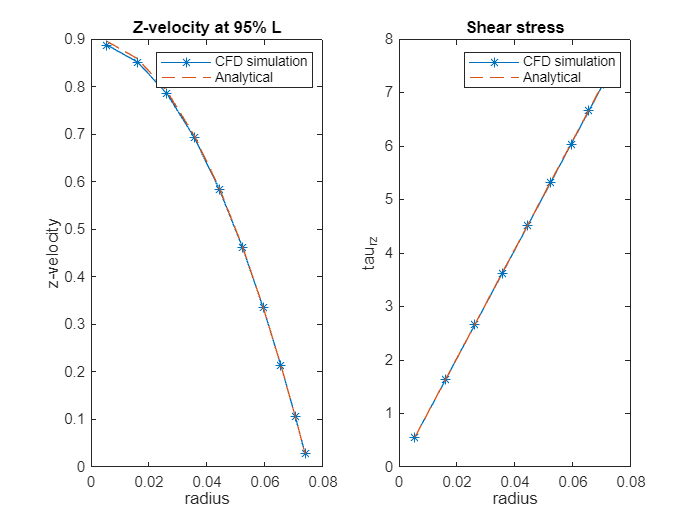

R = D/2;
w = @(r) 2 / (R^2) * (R^2 - r.^2) * Wb;
tau = @(r) 4 * mu / (R^2) * Wb * r; 
analytical_w_r = w(YC);
analytical_tau = tau(YC);

%I consider the velocity at 90% L since it is in the fully developed flow region
z_point1 = ceil(0.9*length(ZC));
z_point2 = ceil(0.95*length(ZC));
dpdz = (P(1,z_point2)-P(1, z_point1))/(ZC(z_point2)-ZC(z_point1));
approx_tau = @(r) -dpdz * r/2;

figure()
subplot(1, 2, 1)
plot(YC, W(:,z_point2), '*-', YC, analytical_w_r, '--')
legend('CFD simulation', 'Analytical')
ylabel('z-velocity')
xlabel('radius')
title('Z-velocity at 95% L')
subplot(1, 2, 2)
plot(YC, approx_tau(YC), '*-', YC, analytical_tau, '--')
legend('CFD simulation', 'Analytical')
ylabel('tau_{rz}')
xlabel('radius')
title('Shear stress')

%Linf errors
Linf_w = max(abs(W(:,z_point2)'-analytical_w_r)./abs(analytical_w_r))

Linf_w = 0.0088

Linf_tau = max(abs(approx_tau(YC)-analytical_tau)./abs(analytical_tau))

Linf_tau = 0.0024

Friction factor copmarison

Re = Wb * D / ni ;
f_an = 64/Re; 
f_cfd = -2*D*dpdz/(rho*Wb^2);
abs(f_an-f_cfd)./abs(f_an)

ans = 78.8116

%for other values of D and Wb
D = 0.2;
Wb = 0.8;
Re = Wb * D / ni %verify under 2000 (laminar flow)

Re = 457.1429

f_an = 64/Re; 
f_cfd = -2*D*dpdz/(rho*Wb^2);
abs(f_an-f_cfd)./abs(f_an)

ans = 0.0024

D = 0.2;
Wb = 0.65;
Re = Wb * D / ni %verify under 2000 (laminar flow)

Re = 371.4286

f_an = 64/Re; 
f_cfd = -2*D*dpdz/(rho*Wb^2);
abs(f_an-f_cfd)./abs(f_an)

ans = 0.2279